#### Interpretation der Parameter in der Differentialgleichung:

Durch ein paar einfache Literaturrecherche stellt man schnell fest, dass das in der Aufgabenstellung angegebene Modell dem SI-Modell (Susceptible-Infective Model) im Gebiet der Epidemiologie entspricht. Nach dem Gegenüberstellen der Differentialgleichungen in den 2 Modellen ergibt sich bezüglich der Parameter folgendes:

k = sqrt(r * c * N), 

mit r als [Replikationsrate](https://de.wikipedia.org/wiki/Replikationsrate), c als Wechselwirkungsterm und N als die Gesamtbevölkerung.

clc
close 
clear

%% 

model = 'Ausbreitungsmodell';
load_system(model)
%Simulink.BlockDiagram.buildRapidAcceleratorTarget(model);
in_k = Simulink.SimulationInput(model);
%in = in.setModelParameter('SimulationMode', 'rapid-accelerator');
in_k = in_k.setModelParameter('EndTime', 100);

#### Bitte verändern Sie die Parameterwerte des Problems so dass sich interessante Zustände (stabiles/instabiles Systemverhalten) ergeben. Beschreiben Sie kurz, ob eine solche Parameterkombination möglich ist. 

- Veränderung y0


%in = in.setModelParameter('RapidAcceleratorUpToDateCheck', 'off');
y0 = 0.01:0.05:0.61;

for p = 1:1:length(y0)
    in_y0(p) = Simulink.SimulationInput(model);
    in_y0(p) = in_y0(p).setVariable('y0', y0(p), 'Workspace', 'Ausbreitungsmodell');
    in_y0(p) = in_y0(p).setVariable('k', 0.1, 'Workspace', 'Ausbreitungsmodell');

end

out = parsim(in_y0, 'ShowProgress', 'on');%Simulate dynamic system multiple times in parallel or serial, 否则需要写for loop & sim命令，一次一次的对仿真循环

[02-Feb-2021 21:24:40] Checking for availability of parallel pool...
[02-Feb-2021 21:24:40] Running simulations...
[02-Feb-2021 21:24:42] Completed 1 of 13 simulation runs
[02-Feb-2021 21:24:42] Completed 2 of 13 simulation runs
[02-Feb-2021 21:24:42] Completed 3 of 13 simulation runs
[02-Feb-2021 21:24:43] Completed 4 of 13 simulation runs
[02-Feb-2021 21:24:43] Completed 5 of 13 simulation runs
[02-Feb-2021 21:24:43] Completed 6 of 13 simulation runs
[02-Feb-2021 21:24:43] Completed 7 of 13 simulation runs
[02-Feb-2021 21:24:43] Completed 8 of 13 simulation runs
[02-Feb-2021 21:24:43] Completed 9 of 13 simulation runs
[02-Feb-2021 21:24:43] Completed 10 of 13 simulation runs
[02-Feb-2021 21:24:43] Completed 11 of 13 simulation runs
[02-Feb-2021 21:24:43] Completed 12 of 13 simulation runs
[02-Feb-2021 21:24:43] Completed 13 of 13 simulation runs


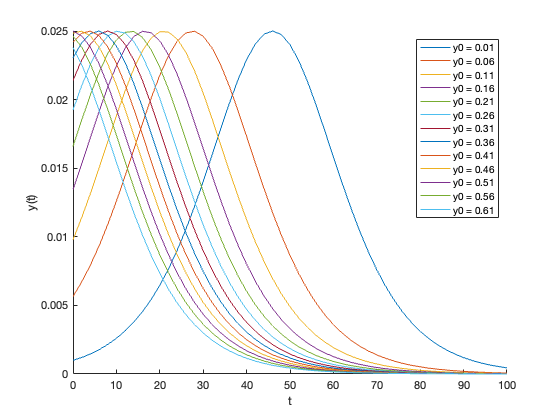


figure 
hold on

%将simulink所选log信号画出来
for p=1:1:length(out)
    plot(out(p).logsout{1}.Values)%要在simulink中将信号线log上！
    legendText_y0{p} = ['y0 = ', num2str(y0(p))];
end
legend(legendText_y0)
xlabel('t')
ylabel('y(t)')
saveas(gcf,fullfile('images', 'yt_y0'), 'jpeg')

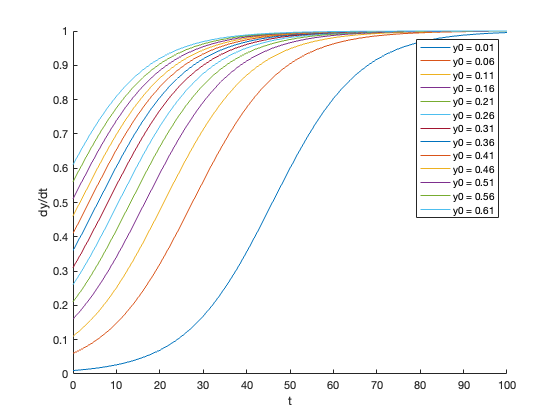


figure
hold on

for p=1:1:length(out)
    plot(out(p).logsout{2}.Values)
    legendText_y0{p} = ['y0 = ', num2str(y0(p))];
end
legend(legendText_y0)
xlabel('t')
ylabel('dy/dt')
saveas(gcf,fullfile('images', 'dydt_y0'), 'jpeg')

 2. Veränderung k

%in = in.setModelParameter('RapidAcceleratorUpToDateCheck', 'off');
k = 0.05:0.05:0.3;

for p = 1:1:length(k)
    in_k(p) = Simulink.SimulationInput(model);
    in_k(p) = in_k(p).setVariable('k', k(p), 'Workspace', 'Ausbreitungsmodell');
    in_k(p) = in_k(p).setVariable('y0', 0.01, 'Workspace', 'Ausbreitungsmodell');

end

out = parsim(in_k, 'ShowProgress', 'on');%Simulate dynamic system multiple times in parallel or serial, 否则需要写for loop & sim命令，一次一次的对仿真循环

[02-Feb-2021 21:24:51] Checking for availability of parallel pool...
[02-Feb-2021 21:24:51] Running simulations...
[02-Feb-2021 21:24:52] Completed 1 of 6 simulation runs
[02-Feb-2021 21:24:52] Completed 2 of 6 simulation runs
[02-Feb-2021 21:24:52] Completed 3 of 6 simulation runs
[02-Feb-2021 21:24:52] Completed 4 of 6 simulation runs
[02-Feb-2021 21:24:52] Completed 5 of 6 simulation runs
[02-Feb-2021 21:24:52] Completed 6 of 6 simulation runs


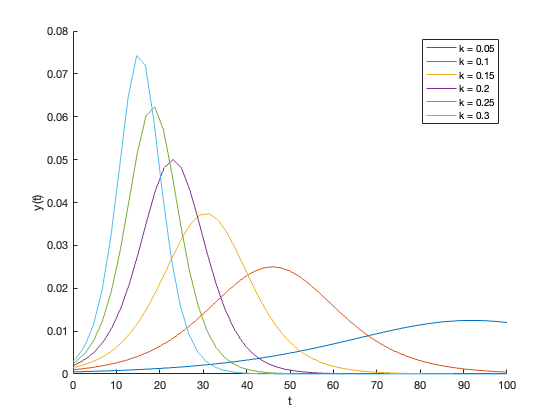


figure 
hold on

%将simulink所选log信号画出来
for p=1:1:length(out)
    plot(out(p).logsout{1}.Values)%要在simulink中将信号线log上！
    legendText_k{p} = ['k = ', num2str(k(p))];
end
legend(legendText_k)
xlabel('t')
ylabel('y(t)')
saveas(gcf,fullfile('images', 'yt_k'), 'jpeg')

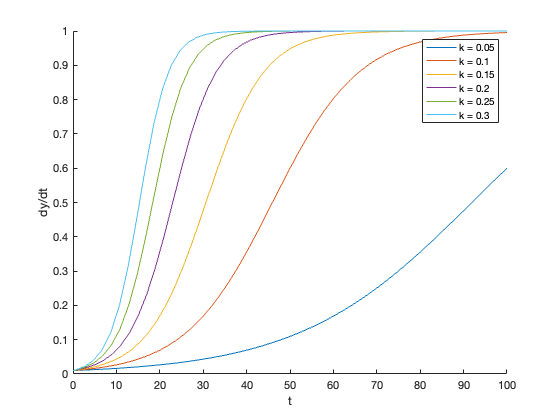


figure
hold on

for p=1:1:length(out)
    plot(out(p).logsout{2}.Values)
    legendText_k{p} = ['k = ', num2str(k(p))];
end
legend(legendText_k)
xlabel('t')
ylabel('dy/dt')
saveas(gcf,fullfile('images', 'dydt_k'), 'jpeg')